# ***Inversion_Noise_grid.mlx***

# Inversion of Noise Slips (Grid)

Το script αυτό αναλαμβάνει τη διαδικασία της Αντιστροφής για τα σύνολα τιμών ολισθήσεων που προέκυψαν από την προσθήκη θορύβου στα συνθετικά δεδομένα σταθμών διατεταγμένων σε πλέγμα (grid).

Εαν έχει προηγηθεί το τρέξιμο του script 'Misfit_Roughness_grid.mlx' ή του 'Inversion_Synthetic_grid.mlx', υπάρχει επιλογή για αυτόματη εισαγωγή των παραμέτρων του ρήγματος. Διαφορετικά, εισάγονται εκ νέου.

Αρχικά θέτουμε ως θέση που τρέχει η Matlab το εσωτερικό του φακέλου 'Project'. Όπου υπάρχει σε σχόλιο το "-->", η μεταβλητή πρέπει να εισαχθεί από το χρήστη ανάλογα με τα δεδομένα του προβλήματος.

% Copyright (c) 2018, Livadas – Stathakopoulos Ioannis (yiannislibad@hotmail.gr)
% Covered by MIT Licence
% Πραγματοποιείται εντός αναφορά σχετικά με χρήση scripts ή λογισμικού τρίτων.

% Επιτρέπουμε στη Matlab να έχει πρόσβαση στα περιεχόμενα του φακέλου Project.
folder = fileparts(which('Inversion_Noise_grid.mlx'));
addpath(genpath(folder));
clearvars

% Φόρτωση του Workspace που αποθηκεύτηκε από το 'Forward_Modeling.mlx'
load Workspace_ForwardModeling_grid.mat

## Εισαγωγή Παραμέτρων Αντιστροφής

% Εισάγετε New_Par = "1": σε περίπτωση που δεν έχει προηγηθεί εκτέλεση του...
% 'Misfit_Roughness_grid.mlx'/'Inversion_Synthetic_grid.mlx', ή επιθυμείτε τον...
% εκ νέου καθορισμό των παραμέτρων της Αντιστροφής,...
% ή New_Par = "0": εάν επιθυμείτε τη διατήρηση των ίδιων τιμών παραμέτρων

New_Par = 0;    % --> Enter "0" or "1"

if New_Par == 0
    if exist('Inv_Par_grid.mat','file')
        load Inv_Par_grid.mat
    else
        disp(['Run ''Misfit_Roughness_grid.mlx''/''Inversion_Synthetic_grid.mlx''' ...
            ' or enter "New_Par" value "1"'])
    end

elseif New_Par == 1
    disp('Enter Inversion Parameters')

    % Εισαγωγή παραμέτρων Αντιστροφής, εάν επιλέξαμε εισαγωγή νέων παραμέτρων
    PR = 0.25;                % --> Poisson ratio (default = 0.25, όμοιο με FM)
    PS = 1.0;                 % --> Patch size [km]
    mR = 0; MR = 360;         % --> min-Max Rake [deg] (a-priori)
    MS = 50.0;                % --> Max Slip [m] (a-priori)  
    tD_A = Dip; bD_A = Dip;   % top-bottom Dip of point A (fault trace) [deg]
    tD_B = Dip; bD_B = Dip;   % top-bottom Dip of point B (fault trace) [deg]
    CN = 10000;               % --> Αριθμός κύκλων

else
    disp('Enter "New_Par" value "0" or "1"')
    
end

## Σύνταξη αρχείων input data

Συντάσσονται τα αρχεία input data για τρεις διευθύνσεις (North, East, Z), τα οποία αποθηκεύονται εντός του υποφακέλου 'GPS_Noise_Grid'.

mkdir GPS_Noise_Grid\


for count = 1:n_models
    
    % Μορφολογία σύνταξης των αρχείων input data (για κάθε...
        % διεύθυνυση [lat lon slip error]
    dispacement_North = [coordinates_grid_trans ...
        1000*uN_New(:,count) 1000*repmat(sigma_uN(1),points_grid,1)];
    displacement_East = [coordinates_grid_trans ...
        1000*uE_New(:,count) 1000*repmat(sigma_uE(1),points_grid,1)];
    displacement_Up = [coordinates_grid_trans ...
        1000*uZ_New(:,count) 1000*repmat(sigma_uZ(1),points_grid,1)];
    
    % Δημιουργία αρχείου input data για uN ('coseismic-ns.txt')   
    fid = fopen(fullfile(pwd,'GPS_Noise_Grid',[num2str(count) ...
        'coseismic-ns.txt']), 'wt');
    fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', dispacement_North');
    fclose(fid);

    % Δημιουργία αρχείου input data για uE ('coseismic-ew.txt')
    fid = fopen(fullfile(pwd,'GPS_Noise_Grid',[num2str(count) ...
        'coseismic-ew.txt']), 'wt');
    fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', displacement_East');
    fclose(fid);    

    % Δημιουργία αρχείου input data για uZ ('coseismic-ud.txt')
    fid = fopen(fullfile(pwd,'GPS_Noise_Grid',[num2str(count) ...
        'coseismic-ud.txt']), 'wt');
    fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', displacement_Up');
    fclose(fid);
    
end

## Εύρεση του ιδανικού συντελεστή k για κάθε μοντέλο

Καθώς κάθε περίπτωση αντιστροφής είναι διαφορετική, το ιδανικό k πρέπει να υπολογιστεί ξεχωριστά για κάθε σύνολο τιμών Slip. Επειδή όμως τα άκρα S, F του ευθύγραμμου τμήματος SF (Line) επιλέγονται έτσι ώστε να απέχουν περίπου την ίδια απόσταση από την εκτίμηση μας για τη θέση του γονάτου (γραφικά), οι SF_values που θα δοκιμαστούν για κάθε σύνολο τιμών θα είναι διαφορετικές. Έτσι το script δεν θα τρέχει ως loop, αλλά πρέπει να προθέτουμε νέα section για κάθε σύνολο τιμών, στην οποία θα αλλάζουμε μόνο τις SF_values και το count.

Σύνολο 1

Υπολογίζεται με δοκιμές ο βέλτιστος k.

count = 1;  % --> Ο αριθμός συνόλου Slip

% !! Καθορισμός τιμών συντελεστή k (Τις επιλέγουμε έτσι ώστε τα άκρα της Line των L-curve να
% ισαπέχουν περίπου από την εκτίμησή μας για το γόνατο (πειραματικά) !!
SF_values = [0.025 0.03 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.20, 0.23, 0.27,...
    0.30, 0.35, 0.40, 0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25, 1.5, 2, 2.5];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));
SF_points = size(SF_values,2);
Table_Converge = zeros([SF_points,3]);
count2 = 0;

for count1 = SF_values

    SF_try = count1;
    count2 = count2+1;
    
    % Δημιουργείται το input αρχείο 'inverse_noise_grid_#.inp' εντός του υποφακέλου 'sdm2011'.
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
        fprintf(fid, [' 1\n ' ...
            num2str(PR) '\n' ...
            ' 1\n' ...
            ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
            num2str(PS) '\n ' ...
            num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
            ' 2\n ' ...
            num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
            num2str(bD_A) '\n ' ...
            num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
            num2str(bD_B) '\n ' ...
            ' 3 1.0 0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
            ' 1.00 0 1 90.0 0.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
            ' 1.00 0 1 90.0 90.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
            ' 1.00 0 1 0.0 0.0\n' ...
            ' ' num2str(CN) '\n' ...
            ' 1 ' num2str(SF_try) '\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
            num2str(count) '_output-ue.dat'' ' ...
            '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
        fclose(fid);
    
    % Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για το σύνολο...
        % δεδομένων με θόρυβο.
            
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
        
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

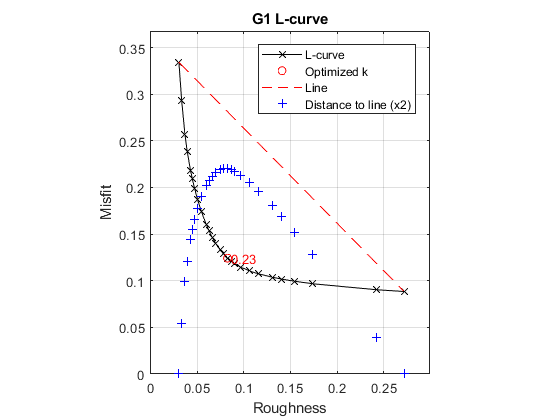


% Σχεδίαση L-curve και εύρεση του γονάτου της
    x = Table_Converge(:,3);
    y = Table_Converge(:,2);

    xf = flip(x); yf = flip(y);

    % Συντεταγμένες των σημείων Misfit-Roughness
    SF_Coord = [xf yf];

    % Πρώτο σημείο
    firstPoint = SF_Coord(1,:);

    % Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
    lineVec = SF_Coord(end,:) - firstPoint;

    % Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
    lineVecN = lineVec / sqrt(sum(lineVec.^2));

    % Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
        % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) H παράλληλη ('vecFromFirstParallel') και κάθετη (vecToLine) συνιστώσα
    % του διανύσματος 'vecFromFirst'.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
    % Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
    [~,idxOfBestPoint] = max(distToLine);
    idxOfBestPoint = SF_points - idxOfBestPoint + 1;

    SF_N_g(count) = SF_values(idxOfBestPoint);

    % Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
    figure()
    p1 = plot(xf,yf,'-xk');
    grid on
    hold on

    p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
    p3 = plot(xf([1 end]),yf([1 end]),'--r');

    p4 = scatter(xf,distToLine*2,'+b');  % --> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ

    t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
    t1.Color = 'red';

    axis equal
    axis([0 1.1*max(xf) 0. 1.1*max(yf)]) % --> Μεταβάλλω ανάλογα
    xlabel('Roughness'); ylabel('Misfit');
    
    legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
        'Distance to line (x2)'});  % --> p4 -> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    title(['G' num2str(count) ' L-curve'])

Σύνολο 2

Υπολογίζεται με δοκιμές ο βέλτιστος k.

count = 2;  % --> Ο αριθμός συνόλου Slip

% !! Καθορισμός τιμών συντελεστή k (Τις επιλέγουμε έτσι ώστε τα άκρα της Line των L-curve να
% ισαπέχουν περίπου από την εκτίμησή μας για το γόνατο (πειραματικά) !!
SF_values = [0.02 0.03 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.2, 0.23, 0.27,...
    0.30, 0.35, 0.40, 0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25, 1.5, 2];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));
SF_points = size(SF_values,2);
Table_Converge = zeros([SF_points,3]);
count2 = 0;

for count1 = SF_values

    SF_try = count1;
    count2 = count2+1;
    
    % Δημιουργείται το input αρχείο 'inverse_noise_grid_#.inp' εντός του υποφακέλου 'sdm2011'.
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
        fprintf(fid, [' 1\n ' ...
            num2str(PR) '\n' ...
            ' 1\n' ...
            ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
            num2str(PS) '\n ' ...
            num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
            ' 2\n ' ...
            num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
            num2str(bD_A) '\n ' ...
            num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
            num2str(bD_B) '\n ' ...
            ' 3 1.0 0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
            ' 1.00 0 1 90.0 0.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
            ' 1.00 0 1 90.0 90.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
            ' 1.00 0 1 0.0 0.0\n' ...
            ' ' num2str(CN) '\n' ...
            ' 1 ' num2str(SF_try) '\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
            num2str(count) '_output-ue.dat'' ' ...
            '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
        fclose(fid);
    
    % Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για το σύνολο...
        % δεδομένων με θόρυβο.
            
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
        
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

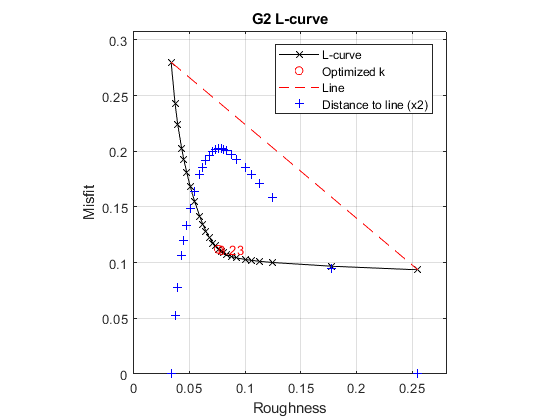


% Σχεδίαση L-curve και εύρεση του γονάτου της
    x = Table_Converge(:,3);
    y = Table_Converge(:,2);

    xf = flip(x); yf = flip(y);

    % Συντεταγμένες των σημείων Misfit-Roughness
    SF_Coord = [xf yf];

    % Πρώτο σημείο
    firstPoint = SF_Coord(1,:);

    % Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
    lineVec = SF_Coord(end,:) - firstPoint;

    % Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
    lineVecN = lineVec / sqrt(sum(lineVec.^2));

    % Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
        % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) H παράλληλη ('vecFromFirstParallel') και κάθετη (vecToLine) συνιστώσα
    % του διανύσματος 'vecFromFirst'.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
    % Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
    [~,idxOfBestPoint] = max(distToLine);
    idxOfBestPoint = SF_points - idxOfBestPoint + 1;

    SF_N_g(count) = SF_values(idxOfBestPoint);

    % Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
    figure()
    p1 = plot(xf,yf,'-xk');
    grid on
    hold on

    p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
    p3 = plot(xf([1 end]),yf([1 end]),'--r');

    p4 = scatter(xf,distToLine*2,'+b');  % --> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ

    t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
    t1.Color = 'red';

    axis equal
    axis([0 1.1*max(xf) 0. 1.1*max(yf)]) % --> Μεταβάλλω ανάλογα
    xlabel('Roughness'); ylabel('Misfit');
    
    legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
        'Distance to line (x2)'});  % --> p4 -> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    title(['G' num2str(count) ' L-curve'])

Σύνολο 3

Υπολογίζεται με δοκιμές ο βέλτιστος k.

count = 3;  % --> Ο αριθμός συνόλου Slip

% !! Καθορισμός τιμών συντελεστή k (Τις επιλέγουμε έτσι ώστε τα άκρα της Line των L-curve να
% ισαπέχουν περίπου από την εκτίμησή μας για το γόνατο (πειραματικά) !!
SF_values = [0.015, 0.02 0.03 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.23, 0.2, 0.27,...
    0.30, 0.35, 0.40, 0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25, 1.5, 2];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));
SF_points = size(SF_values,2);
Table_Converge = zeros([SF_points,3]);
count2 = 0;

for count1 = SF_values

    SF_try = count1;
    count2 = count2+1;
    
    % Δημιουργείται το input αρχείο 'inverse_noise_grid_#.inp' εντός του υποφακέλου 'sdm2011'.
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
        fprintf(fid, [' 1\n ' ...
            num2str(PR) '\n' ...
            ' 1\n' ...
            ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
            num2str(PS) '\n ' ...
            num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
            ' 2\n ' ...
            num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
            num2str(bD_A) '\n ' ...
            num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
            num2str(bD_B) '\n ' ...
            ' 3 1.0 0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
            ' 1.00 0 1 90.0 0.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
            ' 1.00 0 1 90.0 90.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
            ' 1.00 0 1 0.0 0.0\n' ...
            ' ' num2str(CN) '\n' ...
            ' 1 ' num2str(SF_try) '\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
            num2str(count) '_output-ue.dat'' ' ...
            '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
        fclose(fid);
    
    % Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για το σύνολο...
        % δεδομένων με θόρυβο.
            
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
        
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

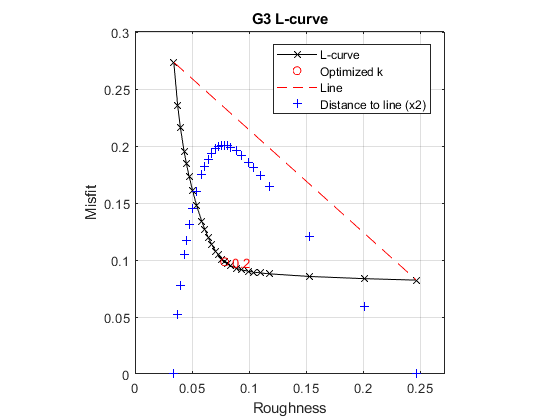


% Σχεδίαση L-curve και εύρεση του γονάτου της
    x = Table_Converge(:,3);
    y = Table_Converge(:,2);

    xf = flip(x); yf = flip(y);

    % Συντεταγμένες των σημείων Misfit-Roughness
    SF_Coord = [xf yf];

    % Πρώτο σημείο
    firstPoint = SF_Coord(1,:);

    % Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
    lineVec = SF_Coord(end,:) - firstPoint;

    % Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
    lineVecN = lineVec / sqrt(sum(lineVec.^2));

    % Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
        % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) H παράλληλη ('vecFromFirstParallel') και κάθετη (vecToLine) συνιστώσα
    % του διανύσματος 'vecFromFirst'.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
    % Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
    [~,idxOfBestPoint] = max(distToLine);
    idxOfBestPoint = SF_points - idxOfBestPoint + 1;

    SF_N_g(count) = SF_values(idxOfBestPoint);

    % Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
    figure()
    p1 = plot(xf,yf,'-xk');
    grid on
    hold on

    p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
    p3 = plot(xf([1 end]),yf([1 end]),'--r');

    p4 = scatter(xf,distToLine*2,'+b');  % --> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ

    t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
    t1.Color = 'red';

    axis equal
    axis([0 1.1*max(xf) 0. 1.1*max(yf)]) % --> Μεταβάλλω ανάλογα
    xlabel('Roughness'); ylabel('Misfit');
    
    legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
        'Distance to line (x2)'});  % --> p4 -> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    title(['G' num2str(count) ' L-curve'])

Σύνολο 4

Υπολογίζεται με δοκιμές ο βέλτιστος k.

count = 4;  % --> Ο αριθμός συνόλου Slip

% !! Καθορισμός τιμών συντελεστή k (Τις επιλέγουμε έτσι ώστε τα άκρα της Line των L-curve να
% ισαπέχουν περίπου από την εκτίμησή μας για το γόνατο (πειραματικά) !!
SF_values = [0.02 0.03 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.2, 0.23, 0.27,...
    0.30, 0.35, 0.40, 0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25, 1.5, 2];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));
SF_points = size(SF_values,2);
Table_Converge = zeros([SF_points,3]);
count2 = 0;

for count1 = SF_values

    SF_try = count1;
    count2 = count2+1;
    
    % Δημιουργείται το input αρχείο 'inverse_noise_grid_#.inp' εντός του υποφακέλου 'sdm2011'.
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
        fprintf(fid, [' 1\n ' ...
            num2str(PR) '\n' ...
            ' 1\n' ...
            ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
            num2str(PS) '\n ' ...
            num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
            ' 2\n ' ...
            num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
            num2str(bD_A) '\n ' ...
            num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
            num2str(bD_B) '\n ' ...
            ' 3 1.0 0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
            ' 1.00 0 1 90.0 0.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
            ' 1.00 0 1 90.0 90.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
            ' 1.00 0 1 0.0 0.0\n' ...
            ' ' num2str(CN) '\n' ...
            ' 1 ' num2str(SF_try) '\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
            num2str(count) '_output-ue.dat'' ' ...
            '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
        fclose(fid);
    
    % Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για το σύνολο...
        % δεδομένων με θόρυβο.
            
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
        
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

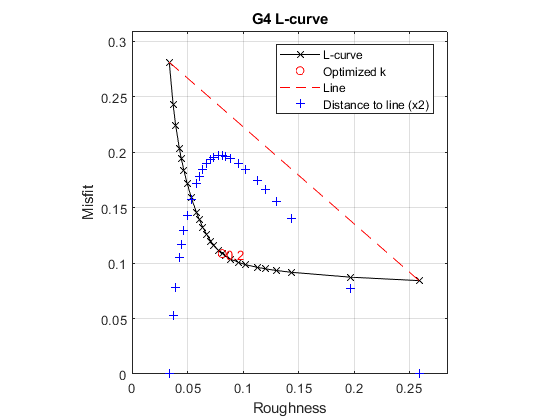


% Σχεδίαση L-curve και εύρεση του γονάτου της
    x = Table_Converge(:,3);
    y = Table_Converge(:,2);

    xf = flip(x); yf = flip(y);

    % Συντεταγμένες των σημείων Misfit-Roughness
    SF_Coord = [xf yf];

    % Πρώτο σημείο
    firstPoint = SF_Coord(1,:);

    % Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
    lineVec = SF_Coord(end,:) - firstPoint;

    % Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
    lineVecN = lineVec / sqrt(sum(lineVec.^2));

    % Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
        % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) H παράλληλη ('vecFromFirstParallel') και κάθετη (vecToLine) συνιστώσα
    % του διανύσματος 'vecFromFirst'.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
    % Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
    [~,idxOfBestPoint] = max(distToLine);
    idxOfBestPoint = SF_points - idxOfBestPoint + 1;

    SF_N_g(count) = SF_values(idxOfBestPoint);

    % Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
    figure()
    p1 = plot(xf,yf,'-xk');
    grid on
    hold on

    p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
    p3 = plot(xf([1 end]),yf([1 end]),'--r');

    p4 = scatter(xf,distToLine*2,'+b');  % --> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ

    t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
    t1.Color = 'red';

    axis equal
    axis([0 1.1*max(xf) 0. 1.1*max(yf)]) % --> Μεταβάλλω ανάλογα
    xlabel('Roughness'); ylabel('Misfit');
    
    legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
        'Distance to line (x2)'});  % --> p4 -> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    title(['G' num2str(count) ' L-curve'])

Σύνολο 5

Υπολογίζεται με δοκιμές ο βέλτιστος k.

count = 5;  % --> Ο αριθμός συνόλου Slip

% !! Καθορισμός τιμών συντελεστή k (Τις επιλέγουμε έτσι ώστε τα άκρα της Line των L-curve να
% ισαπέχουν περίπου από την εκτίμησή μας για το γόνατο (πειραματικά) !!
SF_values = [0.012, 0.02, 0.03, 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.2, 0.23, 0.27,...
    0.30, 0.35, 0.40, 0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));
SF_points = size(SF_values,2);
Table_Converge = zeros([SF_points,3]);
count2 = 0;

for count1 = SF_values

    SF_try = count1;
    count2 = count2+1;
    
    % Δημιουργείται το input αρχείο 'inverse_noise_grid_#.inp' εντός του υποφακέλου 'sdm2011'.
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
        fprintf(fid, [' 1\n ' ...
            num2str(PR) '\n' ...
            ' 1\n' ...
            ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
            num2str(PS) '\n ' ...
            num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
            ' 2\n ' ...
            num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
            num2str(bD_A) '\n ' ...
            num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
            num2str(bD_B) '\n ' ...
            ' 3 1.0 0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
            ' 1.00 0 1 90.0 0.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
            ' 1.00 0 1 90.0 90.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
            ' 1.00 0 1 0.0 0.0\n' ...
            ' ' num2str(CN) '\n' ...
            ' 1 ' num2str(SF_try) '\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
            num2str(count) '_output-ue.dat'' ' ...
            '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
        fclose(fid);
    
    % Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για το σύνολο...
        % δεδομένων με θόρυβο.
            
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
        
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

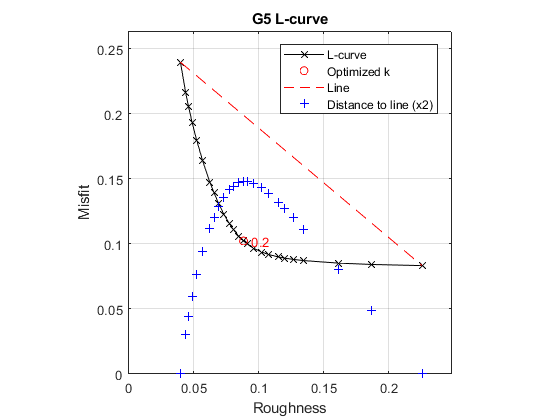


% Σχεδίαση L-curve και εύρεση του γονάτου της
    x = Table_Converge(:,3);
    y = Table_Converge(:,2);

    xf = flip(x); yf = flip(y);

    % Συντεταγμένες των σημείων Misfit-Roughness
    SF_Coord = [xf yf];

    % Πρώτο σημείο
    firstPoint = SF_Coord(1,:);

    % Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
    lineVec = SF_Coord(end,:) - firstPoint;

    % Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
    lineVecN = lineVec / sqrt(sum(lineVec.^2));

    % Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
        % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) H παράλληλη ('vecFromFirstParallel') και κάθετη (vecToLine) συνιστώσα
    % του διανύσματος 'vecFromFirst'.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
    % Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
    [~,idxOfBestPoint] = max(distToLine);
    idxOfBestPoint = SF_points - idxOfBestPoint + 1;

    SF_N_g(count) = SF_values(idxOfBestPoint);

    % Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
    figure()
    p1 = plot(xf,yf,'-xk');
    grid on
    hold on

    p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
    p3 = plot(xf([1 end]),yf([1 end]),'--r');

    p4 = scatter(xf,distToLine*2,'+b');  % --> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ

    t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
    t1.Color = 'red';

    axis equal
    axis([0 1.1*max(xf) 0. 1.1*max(yf)]) % --> Μεταβάλλω ανάλογα
    xlabel('Roughness'); ylabel('Misfit');
    
    legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
        'Distance to line (x2)'});  % --> p4 -> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    title(['G' num2str(count) ' L-curve'])

Σύνολο 6

Υπολογίζεται με δοκιμές ο βέλτιστος k.

count = 6;  % --> Ο αριθμός συνόλου Slip

% !! Καθορισμός τιμών συντελεστή k (Τις επιλέγουμε έτσι ώστε τα άκρα της Line των L-curve να
% ισαπέχουν περίπου από την εκτίμησή μας για το γόνατο (πειραματικά) !!
SF_values = [0.02, 0.03, 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.23, 0.27,...
    0.30, 0.35, 0.40, 0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25, 1.5, 2];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));
SF_points = size(SF_values,2);
Table_Converge = zeros([SF_points,3]);
count2 = 0;

for count1 = SF_values

    SF_try = count1;
    count2 = count2+1;
    
    % Δημιουργείται το input αρχείο 'inverse_noise_grid_#.inp' εντός του υποφακέλου 'sdm2011'.
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
        fprintf(fid, [' 1\n ' ...
            num2str(PR) '\n' ...
            ' 1\n' ...
            ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
            num2str(PS) '\n ' ...
            num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
            ' 2\n ' ...
            num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
            num2str(bD_A) '\n ' ...
            num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
            num2str(bD_B) '\n ' ...
            ' 3 1.0 0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
            ' 1.00 0 1 90.0 0.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
            ' 1.00 0 1 90.0 90.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
            ' 1.00 0 1 0.0 0.0\n' ...
            ' ' num2str(CN) '\n' ...
            ' 1 ' num2str(SF_try) '\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
            num2str(count) '_output-ue.dat'' ' ...
            '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
        fclose(fid);
    
    % Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για το σύνολο...
        % δεδομένων με θόρυβο.
            
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
        
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

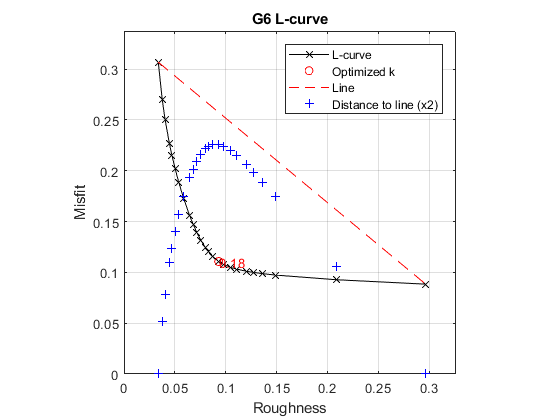


% Σχεδίαση L-curve και εύρεση του γονάτου της
    x = Table_Converge(:,3);
    y = Table_Converge(:,2);

    xf = flip(x); yf = flip(y);

    % Συντεταγμένες των σημείων Misfit-Roughness
    SF_Coord = [xf yf];

    % Πρώτο σημείο
    firstPoint = SF_Coord(1,:);

    % Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
    lineVec = SF_Coord(end,:) - firstPoint;

    % Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
    lineVecN = lineVec / sqrt(sum(lineVec.^2));

    % Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
        % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) H παράλληλη ('vecFromFirstParallel') και κάθετη (vecToLine) συνιστώσα
    % του διανύσματος 'vecFromFirst'.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
    % Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
    [~,idxOfBestPoint] = max(distToLine);
    idxOfBestPoint = SF_points - idxOfBestPoint + 1;

    SF_N_g(count) = SF_values(idxOfBestPoint);

    % Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
    figure()
    p1 = plot(xf,yf,'-xk');
    grid on
    hold on

    p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
    p3 = plot(xf([1 end]),yf([1 end]),'--r');

    p4 = scatter(xf,distToLine*2,'+b');  % --> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ

    t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
    t1.Color = 'red';

    axis equal
    axis([0 1.1*max(xf) 0. 1.1*max(yf)]) % --> Μεταβάλλω ανάλογα
    xlabel('Roughness'); ylabel('Misfit');
    
    legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
        'Distance to line (x2)'});  % --> p4 -> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    title(['G' num2str(count) ' L-curve'])

Σύνολο 7

Υπολογίζεται με δοκιμές ο βέλτιστος k.

count = 7;  % --> Ο αριθμός συνόλου Slip

% !! Καθορισμός τιμών συντελεστή k (Τις επιλέγουμε έτσι ώστε τα άκρα της Line των L-curve να
% ισαπέχουν περίπου από την εκτίμησή μας για το γόνατο (πειραματικά) !!
SF_values = [0.025, 0.03, 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.23, 0.27,...
    0.30, 0.35, 0.40, 0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25, 1.5, 2.2];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));
SF_points = size(SF_values,2);
Table_Converge = zeros([SF_points,3]);
count2 = 0;

for count1 = SF_values

    SF_try = count1;
    count2 = count2+1;
    
    % Δημιουργείται το input αρχείο 'inverse_noise_grid_#.inp' εντός του υποφακέλου 'sdm2011'.
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
        fprintf(fid, [' 1\n ' ...
            num2str(PR) '\n' ...
            ' 1\n' ...
            ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
            num2str(PS) '\n ' ...
            num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
            ' 2\n ' ...
            num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
            num2str(bD_A) '\n ' ...
            num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
            num2str(bD_B) '\n ' ...
            ' 3 1.0 0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
            ' 1.00 0 1 90.0 0.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
            ' 1.00 0 1 90.0 90.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
            ' 1.00 0 1 0.0 0.0\n' ...
            ' ' num2str(CN) '\n' ...
            ' 1 ' num2str(SF_try) '\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
            num2str(count) '_output-ue.dat'' ' ...
            '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
        fclose(fid);
    
    % Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για το σύνολο...
        % δεδομένων με θόρυβο.
            
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
        
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

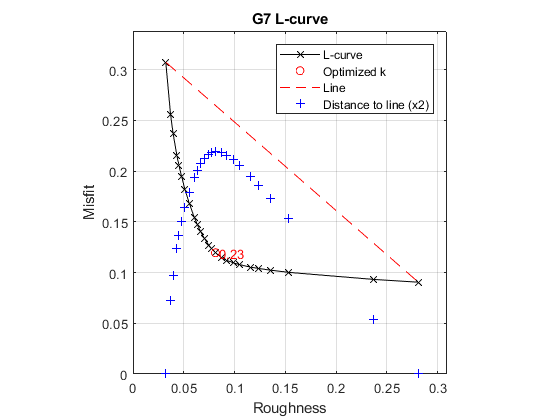


% Σχεδίαση L-curve και εύρεση του γονάτου της
    x = Table_Converge(:,3);
    y = Table_Converge(:,2);

    xf = flip(x); yf = flip(y);

    % Συντεταγμένες των σημείων Misfit-Roughness
    SF_Coord = [xf yf];

    % Πρώτο σημείο
    firstPoint = SF_Coord(1,:);

    % Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
    lineVec = SF_Coord(end,:) - firstPoint;

    % Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
    lineVecN = lineVec / sqrt(sum(lineVec.^2));

    % Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
        % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) H παράλληλη ('vecFromFirstParallel') και κάθετη (vecToLine) συνιστώσα
    % του διανύσματος 'vecFromFirst'.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
    % Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
    [~,idxOfBestPoint] = max(distToLine);
    idxOfBestPoint = SF_points - idxOfBestPoint + 1;

    SF_N_g(count) = SF_values(idxOfBestPoint);

    % Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
    figure()
    p1 = plot(xf,yf,'-xk');
    grid on
    hold on

    p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
    p3 = plot(xf([1 end]),yf([1 end]),'--r');

    p4 = scatter(xf,distToLine*2,'+b');  % --> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ

    t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
    t1.Color = 'red';

    axis equal
    axis([0 1.1*max(xf) 0. 1.1*max(yf)]) % --> Μεταβάλλω ανάλογα
    xlabel('Roughness'); ylabel('Misfit');
    
    legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
        'Distance to line (x2)'});  % --> p4 -> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    title(['G' num2str(count) ' L-curve'])

Σύνολο 8

Υπολογίζεται με δοκιμές ο βέλτιστος k.

count = 8;  % --> Ο αριθμός συνόλου Slip

% !! Καθορισμός τιμών συντελεστή k (Τις επιλέγουμε έτσι ώστε τα άκρα της Line των L-curve να
% ισαπέχουν περίπου από την εκτίμησή μας για το γόνατο (πειραματικά) !!
SF_values = [0.015, 0.02, 0.03, 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.23, 0.27,...
    0.30, 0.35, 0.40, 0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25, 1.5, 2];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));
SF_points = size(SF_values,2);
Table_Converge = zeros([SF_points,3]);
count2 = 0;

for count1 = SF_values

    SF_try = count1;
    count2 = count2+1;
    
    % Δημιουργείται το input αρχείο 'inverse_noise_grid_#.inp' εντός του υποφακέλου 'sdm2011'.
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
        fprintf(fid, [' 1\n ' ...
            num2str(PR) '\n' ...
            ' 1\n' ...
            ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
            num2str(PS) '\n ' ...
            num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
            ' 2\n ' ...
            num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
            num2str(bD_A) '\n ' ...
            num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
            num2str(bD_B) '\n ' ...
            ' 3 1.0 0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
            ' 1.00 0 1 90.0 0.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
            ' 1.00 0 1 90.0 90.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
            ' 1.00 0 1 0.0 0.0\n' ...
            ' ' num2str(CN) '\n' ...
            ' 1 ' num2str(SF_try) '\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
            num2str(count) '_output-ue.dat'' ' ...
            '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
        fclose(fid);
    
    % Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για το σύνολο...
        % δεδομένων με θόρυβο.
            
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
        
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

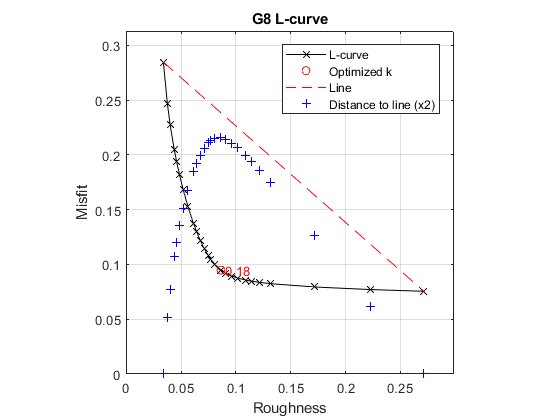


% Σχεδίαση L-curve και εύρεση του γονάτου της
    x = Table_Converge(:,3);
    y = Table_Converge(:,2);

    xf = flip(x); yf = flip(y);

    % Συντεταγμένες των σημείων Misfit-Roughness
    SF_Coord = [xf yf];

    % Πρώτο σημείο
    firstPoint = SF_Coord(1,:);

    % Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
    lineVec = SF_Coord(end,:) - firstPoint;

    % Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
    lineVecN = lineVec / sqrt(sum(lineVec.^2));

    % Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
        % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) H παράλληλη ('vecFromFirstParallel') και κάθετη (vecToLine) συνιστώσα
    % του διανύσματος 'vecFromFirst'.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
    % Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
    [~,idxOfBestPoint] = max(distToLine);
    idxOfBestPoint = SF_points - idxOfBestPoint + 1;

    SF_N_g(count) = SF_values(idxOfBestPoint);

    % Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
    figure()
    p1 = plot(xf,yf,'-xk');
    grid on
    hold on

    p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
    p3 = plot(xf([1 end]),yf([1 end]),'--r');

    p4 = scatter(xf,distToLine*2,'+b');  % --> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ

    t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
    t1.Color = 'red';

    axis equal
    axis([0 1.1*max(xf) 0. 1.1*max(yf)]) % --> Μεταβάλλω ανάλογα
    xlabel('Roughness'); ylabel('Misfit');
    
    legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
        'Distance to line (x2)'});  % --> p4 -> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    title(['G' num2str(count) ' L-curve'])

Σύνολο 9

Υπολογίζεται με δοκιμές ο βέλτιστος k.

count = 9;  % --> Ο αριθμός συνόλου Slip

% !! Καθορισμός τιμών συντελεστή k (Τις επιλέγουμε έτσι ώστε τα άκρα της Line των L-curve να
% ισαπέχουν περίπου από την εκτίμησή μας για το γόνατο (πειραματικά) !!
SF_values = [0.02 0.03 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.23, 0.27,...
    0.30, 0.35, 0.40, 0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25, 1.5, 2];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));
SF_points = size(SF_values,2);
Table_Converge = zeros([SF_points,3]);
count2 = 0;

for count1 = SF_values

    SF_try = count1;
    count2 = count2+1;
    
    % Δημιουργείται το input αρχείο 'inverse_noise_grid_#.inp' εντός του υποφακέλου 'sdm2011'.
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
        fprintf(fid, [' 1\n ' ...
            num2str(PR) '\n' ...
            ' 1\n' ...
            ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
            num2str(PS) '\n ' ...
            num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
            ' 2\n ' ...
            num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
            num2str(bD_A) '\n ' ...
            num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
            num2str(bD_B) '\n ' ...
            ' 3 1.0 0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
            ' 1.00 0 1 90.0 0.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
            ' 1.00 0 1 90.0 90.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
            ' 1.00 0 1 0.0 0.0\n' ...
            ' ' num2str(CN) '\n' ...
            ' 1 ' num2str(SF_try) '\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
            num2str(count) '_output-ue.dat'' ' ...
            '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
        fclose(fid);
    
    % Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για το σύνολο...
        % δεδομένων με θόρυβο.
            
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
        
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

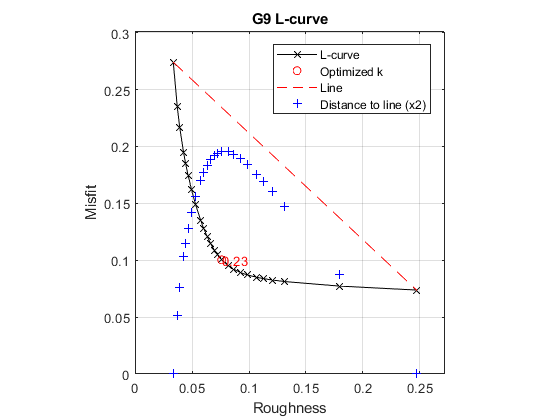


% Σχεδίαση L-curve και εύρεση του γονάτου της
    x = Table_Converge(:,3);
    y = Table_Converge(:,2);

    xf = flip(x); yf = flip(y);

    % Συντεταγμένες των σημείων Misfit-Roughness
    SF_Coord = [xf yf];

    % Πρώτο σημείο
    firstPoint = SF_Coord(1,:);

    % Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
    lineVec = SF_Coord(end,:) - firstPoint;

    % Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
    lineVecN = lineVec / sqrt(sum(lineVec.^2));

    % Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
        % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) H παράλληλη ('vecFromFirstParallel') και κάθετη (vecToLine) συνιστώσα
    % του διανύσματος 'vecFromFirst'.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
    % Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
    [~,idxOfBestPoint] = max(distToLine);
    idxOfBestPoint = SF_points - idxOfBestPoint + 1;

    SF_N_g(count) = SF_values(idxOfBestPoint);

    % Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
    figure()
    p1 = plot(xf,yf,'-xk');
    grid on
    hold on

    p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
    p3 = plot(xf([1 end]),yf([1 end]),'--r');

    p4 = scatter(xf,distToLine*2,'+b');  % --> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ

    t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
    t1.Color = 'red';

    axis equal
    axis([0 1.1*max(xf) 0. 1.1*max(yf)]) % --> Μεταβάλλω ανάλογα
    xlabel('Roughness'); ylabel('Misfit');
    
    legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
        'Distance to line (x2)'});  % --> p4 -> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    title(['G' num2str(count) ' L-curve'])

Σύνολο 10

Υπολογίζεται με δοκιμές ο βέλτιστος k.

count = 10;  % --> Ο αριθμός συνόλου Slip

% !! Καθορισμός τιμών συντελεστή k (Τις επιλέγουμε έτσι ώστε τα άκρα της Line των L-curve να
% ισαπέχουν περίπου από την εκτίμησή μας για το γόνατο (πειραματικά) !!
SF_values = [0.02 0.03 0.05, 0.06, 0.07, 0.08, 0.1, 0.12, 0.15, 0.18, 0.23, 0.27,...
    0.30, 0.35, 0.40, 0.45, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 1.25, 1.5, 2];  % --> Οι τιμές του συντ. k

SF_values_names = num2str((SF_values'));
SF_points = size(SF_values,2);
Table_Converge = zeros([SF_points,3]);
count2 = 0;

for count1 = SF_values

    SF_try = count1;
    count2 = count2+1;
    
    % Δημιουργείται το input αρχείο 'inverse_noise_grid_#.inp' εντός του υποφακέλου 'sdm2011'.
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
        fprintf(fid, [' 1\n ' ...
            num2str(PR) '\n' ...
            ' 1\n' ...
            ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
            num2str(PS) '\n ' ...
            num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
            ' 2\n ' ...
            num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
            num2str(bD_A) '\n ' ...
            num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
            num2str(bD_B) '\n ' ...
            ' 3 1.0 0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
            ' 1.00 0 1 90.0 0.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
            ' 1.00 0 1 90.0 90.0\n' ...
            ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
            '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
            ' 1.00 0 1 0.0 0.0\n' ...
            ' ' num2str(CN) '\n' ...
            ' 1 ' num2str(SF_try) '\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
            ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
            num2str(count) '_output-ue.dat'' ' ...
            '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
        fclose(fid);
    
    % Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για το σύνολο...
        % δεδομένων με θόρυβο.
            
    cd sdm2011
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
    cd ..\.
    
    % Δημιουργία του Πίνακα Table_Converge
    Converge = importdata('converge.dat');
    Table_Converge(count2,1) = SF_try;
    Table_Converge(count2,[2 3]) = Converge.data(end,[3 4]);
        
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

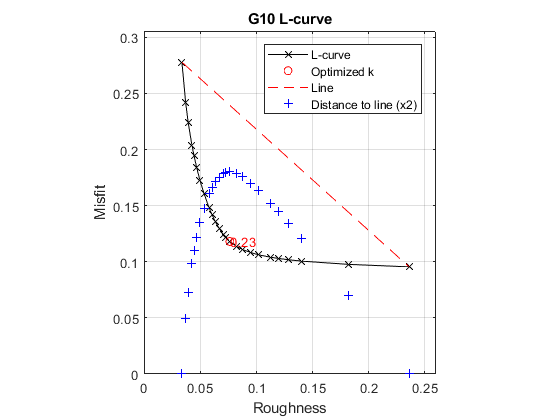


% Σχεδίαση L-curve και εύρεση του γονάτου της
    x = Table_Converge(:,3);
    y = Table_Converge(:,2);

    xf = flip(x); yf = flip(y);

    % Συντεταγμένες των σημείων Misfit-Roughness
    SF_Coord = [xf yf];

    % Πρώτο σημείο
    firstPoint = SF_Coord(1,:);

    % Το διάνυσμα από το πρώτο ως το τελευταίο σημείο. Αυτή είναι η γραμμή.
    lineVec = SF_Coord(end,:) - firstPoint;

    % Κανονικοποίηση του διανύσματος (προκύπτει το μοναδιαίο)
    lineVecN = lineVec / sqrt(sum(lineVec.^2));

    % Εύρεση της απόστασης κάθε σημείου [Roughness, Misfit] από τη γραμμή:
        % 1) Το διάνυσμα για κάθε σημείο [Roughness, Misfit] από το πρώτο σημείο.
    vecFromFirst = bsxfun(@minus, SF_Coord, firstPoint);
    
    % 2) H παράλληλη ('vecFromFirstParallel') και κάθετη (vecToLine) συνιστώσα
    % του διανύσματος 'vecFromFirst'.
    scalarProduct = dot(vecFromFirst, repmat(lineVecN,SF_points,1), 2);
    vecFromFirstParallel = scalarProduct * lineVecN;  % Το παράλληλο διάνυσμα
    vecToLine = vecFromFirst - vecFromFirstParallel;  % Το κάθετο διάνυσμα

    % Η απόσταση από τη γραμμή είναι το μέτρο του 'vecToLine' (κάθετο διάνυσμα)
    distToLine = sqrt(sum(vecToLine.^2,2));
    
    % Υπολογισμός σημείου max απόστασης - ιδανικού συντελεστή k:
    [~,idxOfBestPoint] = max(distToLine);
    idxOfBestPoint = SF_points - idxOfBestPoint + 1;

    SF_N_g(count) = SF_values(idxOfBestPoint);

    % Σχεδίαση της απόστασης των σημείων [Roughness, Misfit] από τη γραμμή
    figure()
    p1 = plot(xf,yf,'-xk');
    grid on
    hold on

    p2 = plot(x(idxOfBestPoint),y(idxOfBestPoint),'or');
  
    p3 = plot(xf([1 end]),yf([1 end]),'--r');

    p4 = scatter(xf,distToLine*2,'+b');  % --> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ

    t1 = text(x(idxOfBestPoint),y(idxOfBestPoint),SF_values_names(idxOfBestPoint,:));
    t1.Color = 'red';

    axis equal
    axis([0 1.1*max(xf) 0. 1.1*max(yf)]) % --> Μεταβάλλω ανάλογα
    xlabel('Roughness'); ylabel('Misfit');
    
    legend([p1,p2,p3,p4],{'L-curve','Optimized k','Line',...
        'Distance to line (x2)'});  % --> p4 -> Μεταβάλλω για καλύτερη απεικόνιση ή αφαιρώ
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    title(['G' num2str(count) ' L-curve'])

## --> Αντιστροφή με χρήση του ιδανικού συντελεστή k.

Δημιουργούνται τα input αρχεία '**inverse_noise_grid_#.inp**' εντός του υποφακέλου 'sdm2011'.

for count = 1:n_models
        
    fid = fopen(fullfile(pwd,'sdm2011',['inverse_noise_grid_' num2str(count) '.inp']), 'wt');
    fprintf(fid, [' 1\n ' ...
        num2str(PR) '\n' ...
        ' 1\n' ...
        ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
        num2str(PS) '\n ' ...
        num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
        ' 2\n ' ...
        num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
        num2str(bD_A) '\n ' ...
        num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
        num2str(bD_B) '\n ' ...
        ' 3 1.0 0\n' ...
        ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ns.txt'' ' ...
        '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ns.txt''\n' ...
        ' 1.00 0 1 90.0 0.0\n' ...
        ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ew.txt'' ' ...
        '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ew.txt''\n' ...
        ' 1.00 0 1 90.0 90.0\n' ...
        ' ''../GPS_Noise_Grid/' num2str(count) ['coseismic-ud.txt'' ' ...
        '''../GPS_Noise_Grid/'] num2str(count) 'coseismic-ud.txt''\n' ...
        ' 1.00 0 1 0.0 0.0\n' ...
        ' ' num2str(CN) '\n' ...
        ' 1 ' num2str(SF_N_g(count)) '\n' ...
        ' ''inverse_noise_grid_' num2str(count) '_slip.dat''\n' ...
        ' ''inverse_noise_grid_' num2str(count) '_output-un.dat'' ''inverse_noise_grid_' ...
        num2str(count) '_output-ue.dat'' ' ...
        '''inverse_noise_grid_' num2str(count) '_output-uz.dat''']);
    fclose(fid);
    
end

Bάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' για κάθε σύνολο δεδομένων με χαμηλό θόρυβο.

cd sdm2011

for count = 1:n_models
    commandfile = fopen('commandfile.txt','wt');
    fprintf(commandfile,['inverse_noise_grid_' num2str(count) '.inp']);
    fclose(commandfile);
    system('sdm2011.exe < commandfile.txt');
end

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     


delete commandfile.txt
cd ..\.

% Αποθήκευση των παραμέτρων
save ('Inv_Par_grid.mat','SF_N_g','-append')